**Carlo Colizzi & Daniel Park | ModSim 2020 Final Project**

# **Ball Bouncing Simulation**

## **Question: ***How will different materials and launch heights of a ball affect its position trajectory?*

## **Methodology/Model: **

### Ball Launch Simulation

First, we decided to use the kinematic equations of motion to come up with a first iteration of the model

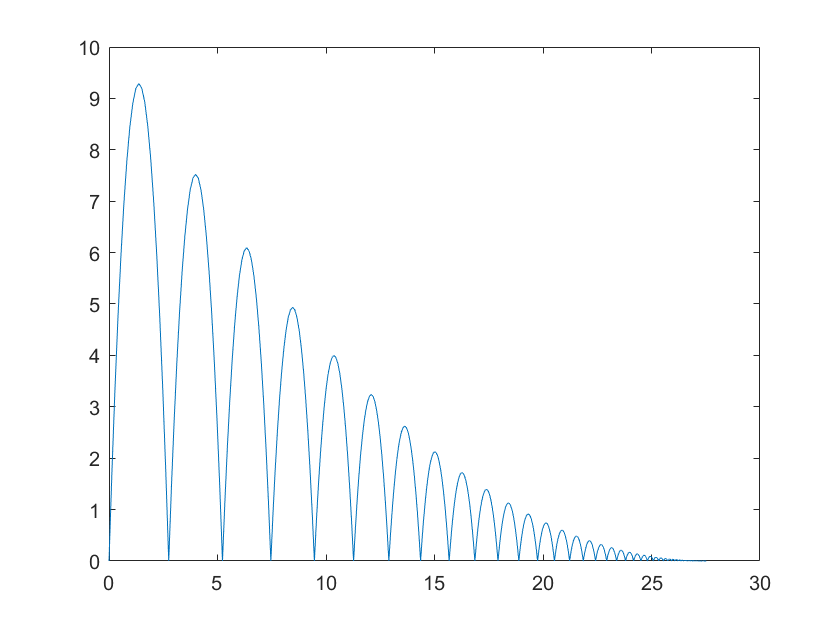

clf
ball_bounce
plot(x,y)

### **ODE45 implementation**

After having develped this model using the kinematic equations, we transferred it to second order differential equations.

**dvdt = -g**

**dxdt = v**

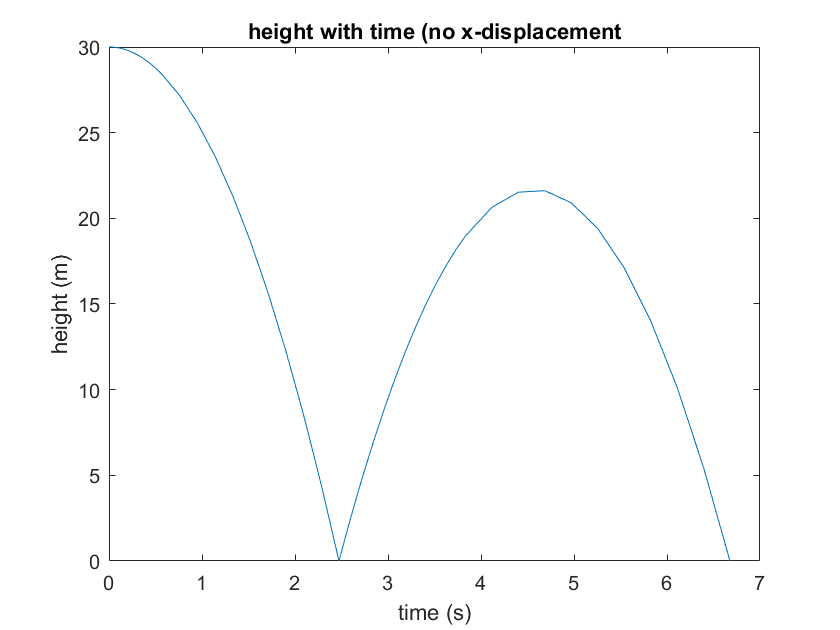

clf
[T, H] = bouncing_y(30);
plot(T, H(:,1), "-"); % position
%hold on
%plot(T, H(:,2), "--"); % velocity
xlabel("time (s)")
ylabel("height (m)")
title("height with time (no x-displacement")

During this third iteration, we decided to put our code in a loop to simulate more bounces

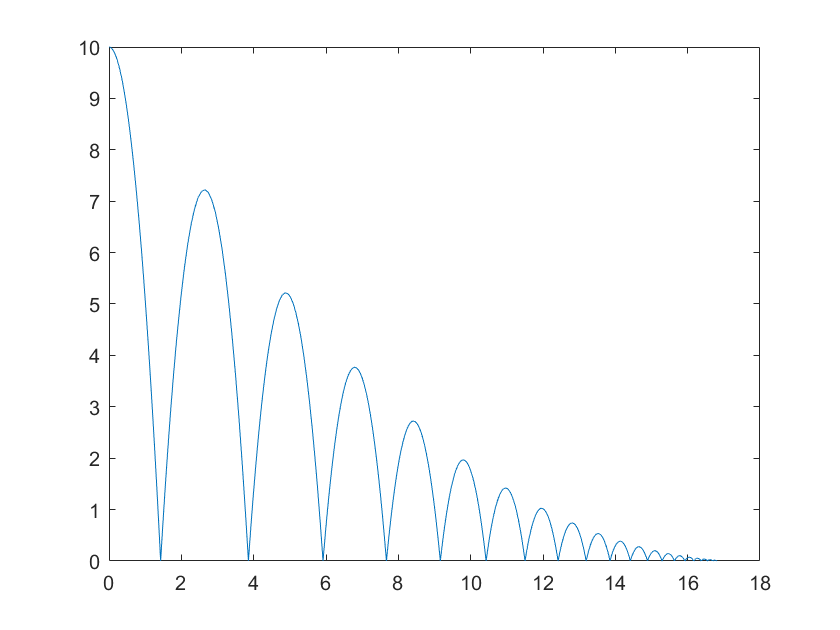

clf; figure
[x, y] = bouncing_xy(10, 1);
plot(x, y(:, 1))

### Sweeping Heights

clf; figure
height = [8:1:15];

height =      8     9    10    11    12    13    14    15


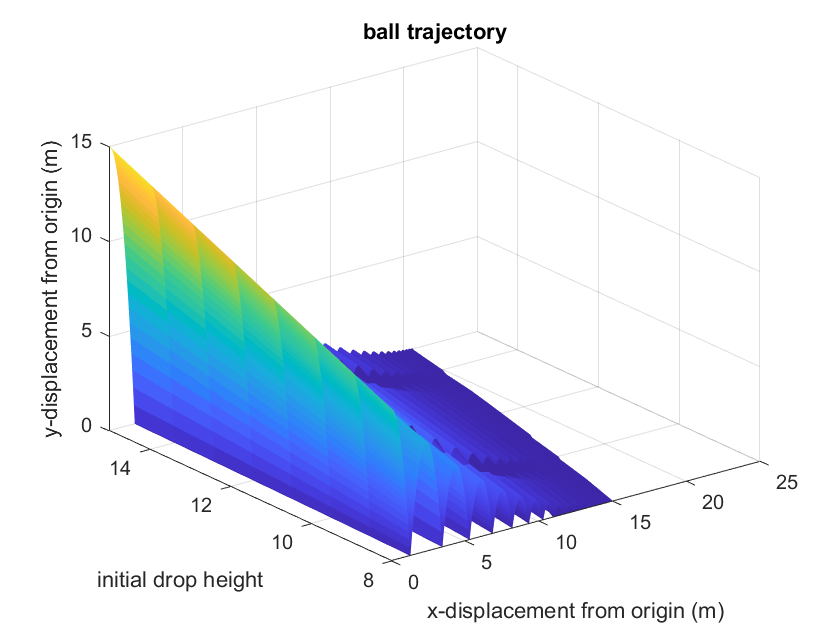

X = zeros(5000, length(height));
Y = zeros(5000, length(height));
Z = zeros(5000, length(height));

for i = 1:length(height)
[x, y] = bouncing_xy(height(i), 1, 0.85);

X(1:length(x), i) = x;
Y(1:length(y), i) = y(:, 1);
Z(1:length(x), i) = height(i).*ones(size(x(i)));

end

surf(X, Z, Y, "EdgeColor","none"); colormap("default")

ylim([height(1), height(end)])
xlabel("x-displacement from origin (m)")
zlabel("y-displacement from origin (m)")
ylabel("initial drop height")
title("ball trajectory")

### Sweeping COR

clf; figure
cor = [0.7:0.1:1]

cor =     0.7000    0.8000    0.9000    1.0000


X = zeros(5000, length(cor));
Y = zeros(5000, length(cor));
Z = zeros(5000, length(cor));

for i = 1:length(cor)

[x, y] = bouncing_xy(10, 1, cor);

X(1:length(x), i) = x;
Y(1:length(y), i) = y(:, 1);
Z(1:length(x), i) = cor(i).*ones(size(x(i)));
end

Error using odearguments (line 95)
BOUNCING_XY/RISE returns a vector of length 2, but the length of initial conditions vector is 5. The vector returned by BOUNCING_XY/RISE and the initial conditions vector must have the same number of elements.

Error in ode45 (line 115)
  odearguments(FcnHandlesUsed, solver_name, ode, tspan, y0, options, varargin);

Error in 

surf(X, Z, Y, "EdgeColor","none"); colormap("default")

ylim([height(1), height(end)])
xlabel("x-displacement from origin (m)")
zlabel("y-displacement from origin (m)")
ylabel("cor")
title("ball trajectory")

## **Results:**

## **Interpretation:**

## **Works Cited:**

Newton's Physics Equations: [https://www.physicsclassroom.com/calcpad/newtlaws](https://www.physicsclassroom.com/calcpad/newtlaws)